# **各向异性的静磁幻觉装置**

**        基于磁性材料和拉普拉斯方程，文献[1]提出并设计了静态磁幻觉设备——当用磁性的探测器探测时，它可以将一个特定物体探测成另外一个物体。例如：假如地下被埋了一个地雷，当利用新型电磁材料覆盖到地雷表面时，对其进行电磁扫描时，得到的地雷会显示为石头。**

**        与**[**各向同性的静磁幻觉装置**](matlab:open('..\C 第三章 静磁场\C8_Isotropic_Static_Magnetic_Illusion_Device.mlx'))**类似，对于幻觉设备，半径为**$r=R_1$**的圆代表磁导率为**$\mu =\mu_0$**的原始物体，在原始物 体上覆盖着一层半径为**$R_1 <r<R_2$**磁导率为**$\mu =\mu_2$**的幻觉套层，放置在的区域为磁导率为**$\mu_3 =1$**的背景区域；半径为 **$R_2$**的圆代表放在材料磁导率为**$\mu =\mu_3$**背景下的磁导率为**$\mu =\mu_1$**的幻觉物体。设两种情况下在区域 **$r>R_2$**内的磁场分 布完全一样，通过对拉普拉斯方程**$\nabla^2 \phi_m =0$**进行分离变量，并匹配边界条件，计算得到**$R_1 <r<R_2$**幻觉套层区域内的磁导率分布可以表达为：**

 
$$\mu_2 =\sqrt{\mu_{2r} \mu_{2\theta } }=\frac{n\left(\mu_1 -\mu_0 \right)}{2}\pm \frac{\sqrt{n^2 {\left(\mu_1 -\mu_0 \right)}^2 +4\mu_0 \mu_1 }}{2}$$


**        其中，**$n=\frac{{\left(R_2 /R_2 \right)}^{2l} +1}{{\left(R_2 /R_2 \right)}^{2l} +1}$**,**$l=\sqrt{\frac{\mu_{2\theta } }{\mu_{2r} }}$

**        仿真中设**$R_1 =5\textrm{mm}$**，**$R_2 =10\textrm{mm}$**，**$\mu_0 =2$**，**$\mu_1 =20$**。对各向异性的情况，设**$l=\sqrt{\mu_{2\theta } /\mu_{2r} }=2$**，计算可得**$\mu_{2\theta } =44\ldotp 4$**，**$\mu_{2r} =11\ldotp 1$

**        用pdetool仿真：**

- **幻形目标模型的磁势分布：**

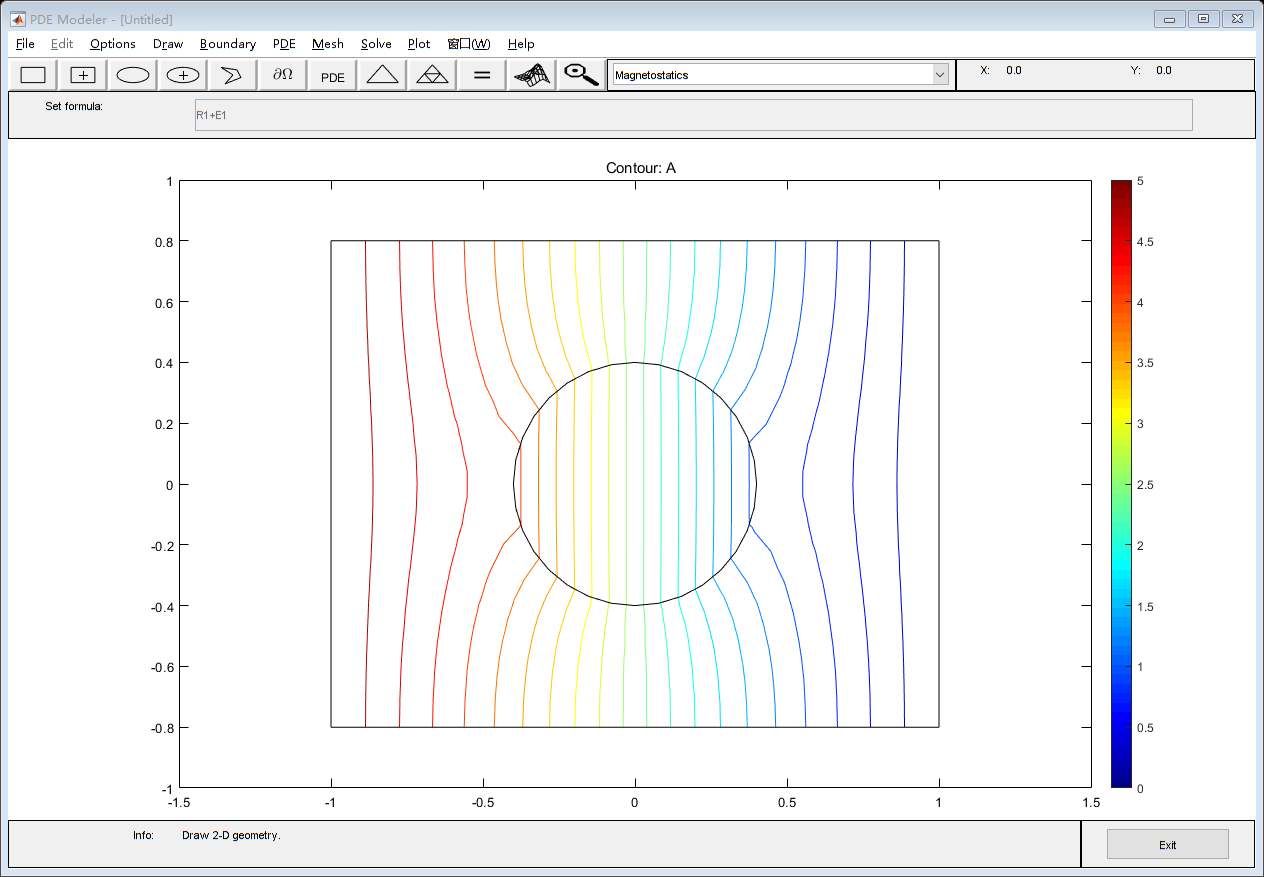

With_Illusion_Device

- **使用幻形材料包裹金属柱的磁势分布：**

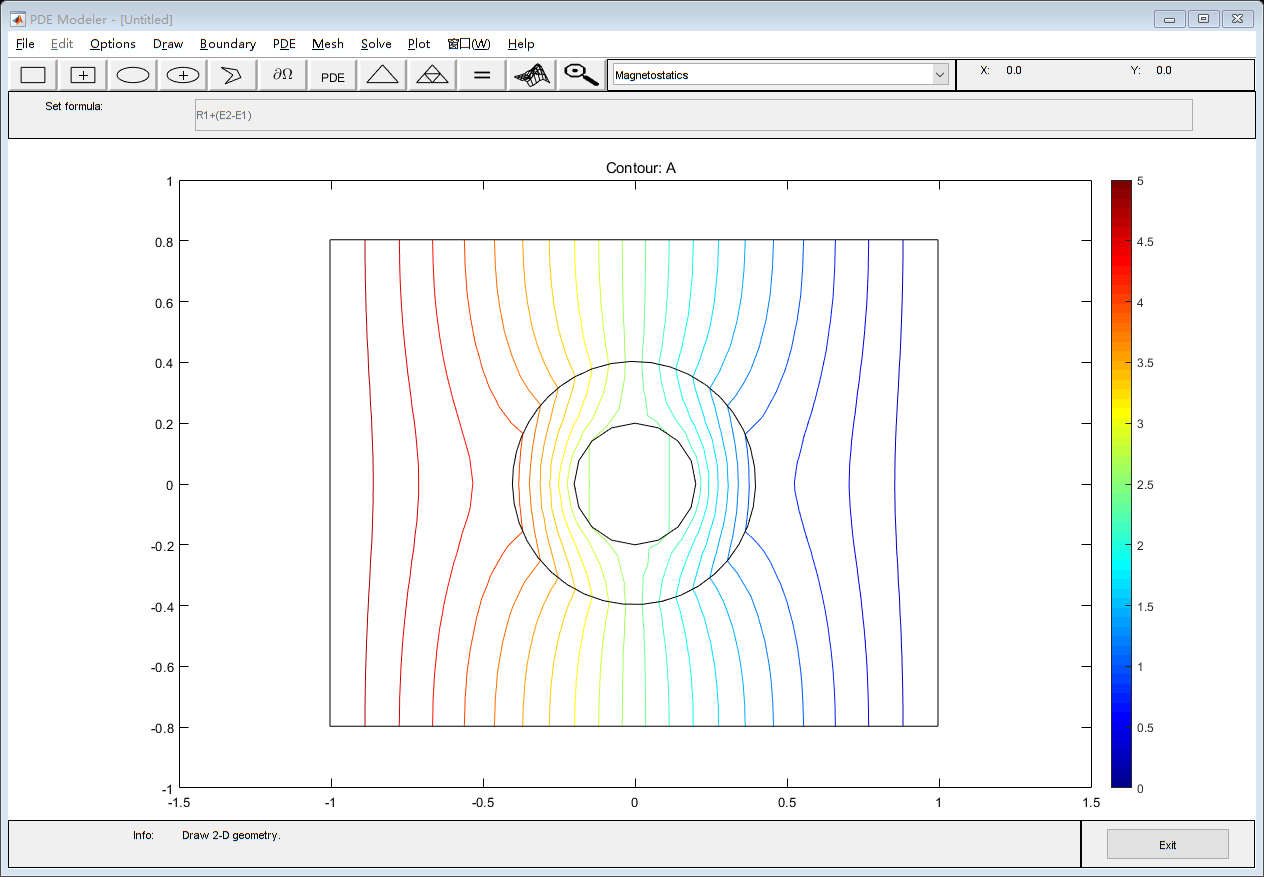

Illusion_Object_Model

**        对比可知两图中在**$r>R_2$**区域内的磁场分布基本与幻觉物体的磁场分布一模一样。因此，认为探测器可将一个覆盖有各向同性或各向异性幻觉套层材料的物体误探测为另一种物体。**

function Illusion_Object_Model
    [pde_fig,ax]=pdeinit;
    pdetool('appl_cb',6);
    set(ax,'DataAspectRatio',[1 1 1]);
    set(ax,'PlotBoxAspectRatio',[1.5 1 1]);
    set(ax,'XLim',[-1.5 1.5]);
    set(ax,'YLim',[-1 1]);
    set(ax,'XTickMode','auto');
    set(ax,'YTickMode','auto');
    
    % Geometry description:
    pderect([-1.0032894736842097 0.99671052631579027 0.80328947368421066 -0.79671052631578942],'R1');
    pdeellip(0,0,0.20000000000000001,0.20000000000000001,...
    0,'E1');
    pdeellip(-0.0032894736842097316,0.0032894736842106198,0.40000000000000002,0.40000000000000002,...
    0,'E2');
    set(findobj(get(pde_fig,'Children'),'Tag','PDEEval'),'String','R1+(E2-E1)')
    
    % Boundary conditions:
    pdetool('changemode',0)
    pdesetbd(4,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(3,...
    'dir',...
    1,...
    '1',...
    '5')
    pdesetbd(2,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(1,...
    'dir',...
    1,...
    '1',...
    '0')
    
    % Mesh generation:
    setappdata(pde_fig,'Hgrad',1.3);
    setappdata(pde_fig,'refinemethod','regular');
    setappdata(pde_fig,'jiggle',char('on','mean',''));
    setappdata(pde_fig,'MesherVersion','preR2013a');
    pdetool('initmesh')
    pdetool('refine')
    
    % PDE coefficients:
    pdeseteq(1,...
    '1./(1)!1./(22.2)!1./(2)',...
    '0.0!0.0!0.0',...
    '0!0!0',...
    '1.0!1.0!1.0',...
    '0:10',...
    '0.0',...
    '0.0',...
    '[0 100]')
    setappdata(pde_fig,'currparam',...
    ['1!22.2!2';...
    '0!0!0   '])
    
    % Solve parameters:
    setappdata(pde_fig,'solveparam',...
    char('0','1680','10','pdeadworst',...
    '0.5','longest','0','1E-4','','fixed','Inf'))
    
    % Plotflags and user data strings:
    setappdata(pde_fig,'plotflags',[1 1 1 1 1 1 7 1 0 1 0 1 0 1 0 0 0 1]);
    setappdata(pde_fig,'colstring','');
    setappdata(pde_fig,'arrowstring','');
    setappdata(pde_fig,'deformstring','');
    setappdata(pde_fig,'heightstring','');
    
    % Solve PDE:
    pdetool('solve')
end

function With_Illusion_Device
    [pde_fig,ax]=pdeinit;
    pdetool('appl_cb',6);
    set(ax,'DataAspectRatio',[1 1 1]);
    set(ax,'PlotBoxAspectRatio',[1.5 1 1]);
    set(ax,'XLim',[-1.5 1.5]);
    set(ax,'YLim',[-1 1]);
    set(ax,'XTickMode','auto');
    set(ax,'YTickMode','auto');
    
    % Geometry description:
    pderect([-1 1 0.80000000000000004 -0.80000000000000004],'R1');
    pdeellip(0,0,0.40000000000000002,0.40000000000000002,...
    0,'E1');
    set(findobj(get(pde_fig,'Children'),'Tag','PDEEval'),'String','R1+E1')
    
    % Boundary conditions:
    pdetool('changemode',0)
    pdesetbd(4,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(3,...
    'dir',...
    1,...
    '1',...
    '5')
    pdesetbd(2,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(1,...
    'dir',...
    1,...
    '1',...
    '0')
    
    % Mesh generation:
    setappdata(pde_fig,'Hgrad',1.3);
    setappdata(pde_fig,'refinemethod','regular');
    setappdata(pde_fig,'jiggle',char('on','mean',''));
    setappdata(pde_fig,'MesherVersion','preR2013a');
    pdetool('initmesh')
    pdetool('refine')
    
    % PDE coefficients:
    pdeseteq(1,...
    '1./(1)!1./(10)',...
    '0.0!0.0',...
    '0!0',...
    '1.0!1.0',...
    '0:10',...
    '0.0',...
    '0.0',...
    '[0 100]')
    setappdata(pde_fig,'currparam',...
    ['1!10';...
    '0!0 '])
    
    % Solve parameters:
    setappdata(pde_fig,'solveparam',...
    char('0','1476','10','pdeadworst',...
    '0.5','longest','0','1E-4','','fixed','Inf'))
    
    % Plotflags and user data strings:
    setappdata(pde_fig,'plotflags',[1 1 1 1 1 1 7 1 0 1 0 1 0 1 0 0 0 1]);
    setappdata(pde_fig,'colstring','');
    setappdata(pde_fig,'arrowstring','');
    setappdata(pde_fig,'deformstring','');
    setappdata(pde_fig,'heightstring','');
    
    % Solve PDE:
    pdetool('solve')

end

**        参考文献：**

**                [1] 鲁翠. 基于人工电磁材料的多功能电磁装置及磁幻觉装置研究[D].兰州大学,2017.**